**Scratch Assay Migration Analysis Program**

Copyright © 2023 Elizabeth Bowen, UCLA

Notes: Selecting parameters will automatically run each section, but the Run button @ bottom of each section can be used to run a section without changing the parameters.

**1. Blur Image & Convert to Grayscale**

Put in the file path to the folder with the image you want to use, and enter the file name into the imgTitle field, then click enter:

% Make sure that you're in the folder with the images you want to use
%loadImage("C3 0h.tif");
addpath("/Users/elizabeth 1/Desktop/Wu Lab/Kaileys Images/Scratch Assay Analysis Package"); %load in functions for this package
cd ("/Users/elizabeth 1/Desktop/Wu Lab/Kaileys Images/9a_Migration Analysis/9a_Experiment/9a_Experiment_24hr");
imgTitle = "E3 24h.tif";
imgTitle = string(imgTitle);
img = imread(imgTitle); %read in image
img = rgb2gray(img); %convert to grayscale
img_blurred = imgaussfilt(img);

 
fprintf('Image blurred & converted to grayscale:')

Image blurred & converted to grayscale:

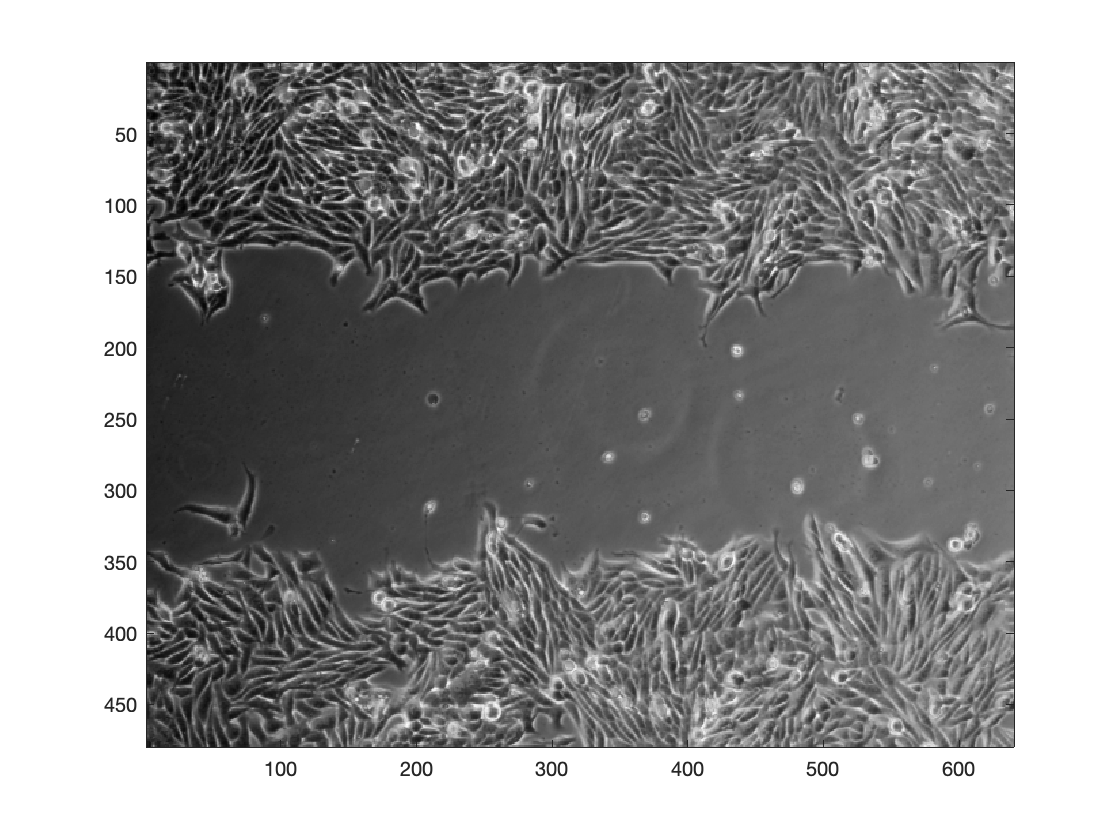

figure %generate new standard-sized figure window
subplot(1,1,1) %undo montage subplotting
imagesc(img_blurred), colormap gray

**2. Select a threshold to binarize the image. **Use the checkboxes to select either adaptive or manual thresholding & set the corresponding parameter. If adpative, the default sensitivity is 0.5. Change if necessary. 

- adaptive thresholding is helpful when the image is not uniform such as when there's a light source in only one part of the image

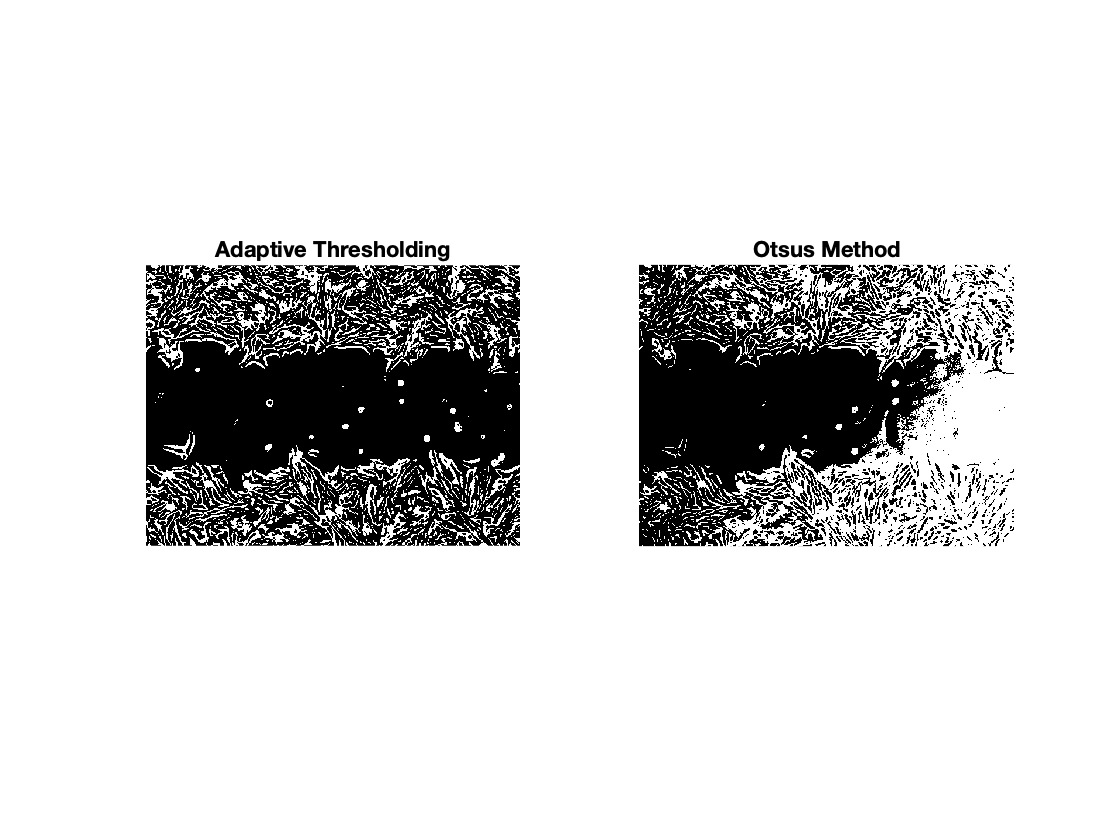

%determine threshold to use based on which image we're using


%to run adaptive thresholding, make sure to check adaptice_thresholding,
%and uncheck manual_thresholding.
threshold_otsu = graythresh(img_blurred);
adaptive_sensitivity = 0.5;

bw_adaptive = imbinarize(img_blurred,'adaptive','sensitivity',adaptive_sensitivity); %adaptive thresholding-- lower=favors background, higher=favors foreground
bw_otsu = imbinarize(img_blurred, threshold_otsu);

 

figure;
subplot(1,2,1);
imshow(bw_adaptive);
title('Adaptive Thresholding');
subplot(1,2,2);
imshow(bw_otsu);
title('Otsus Method');



adaptive_thresholding = true;
if adaptive_thresholding & manual_thresholding == 0
    bw = imbinarize(img_blurred,'adaptive','sensitivity',adaptive_sensitivity); %adaptive thresholding-- lower=favors background, higher=favors foreground
end

%if adaptive thresholding doesn't work, you can input a manual threshold
%using the code below. Make sure to check manual_thresholding, and uncheck
%adaptive_thresholding.
% manual_thresholding = false; % this will run if both are checked
% if manual_thresholding
%     manual_threshold = 0.28;%lower: favors foreground, higher: favors background
%     bw = imbinarize(img_blurred,manual_threshold); %manual thresholding
% end

otsus_method = false; 
if otsus_method
    % Threshold the image
    bw = imbinarize(img_blurred, threshold_otsu);
end



fprintf('Binarized:')

Binarized:

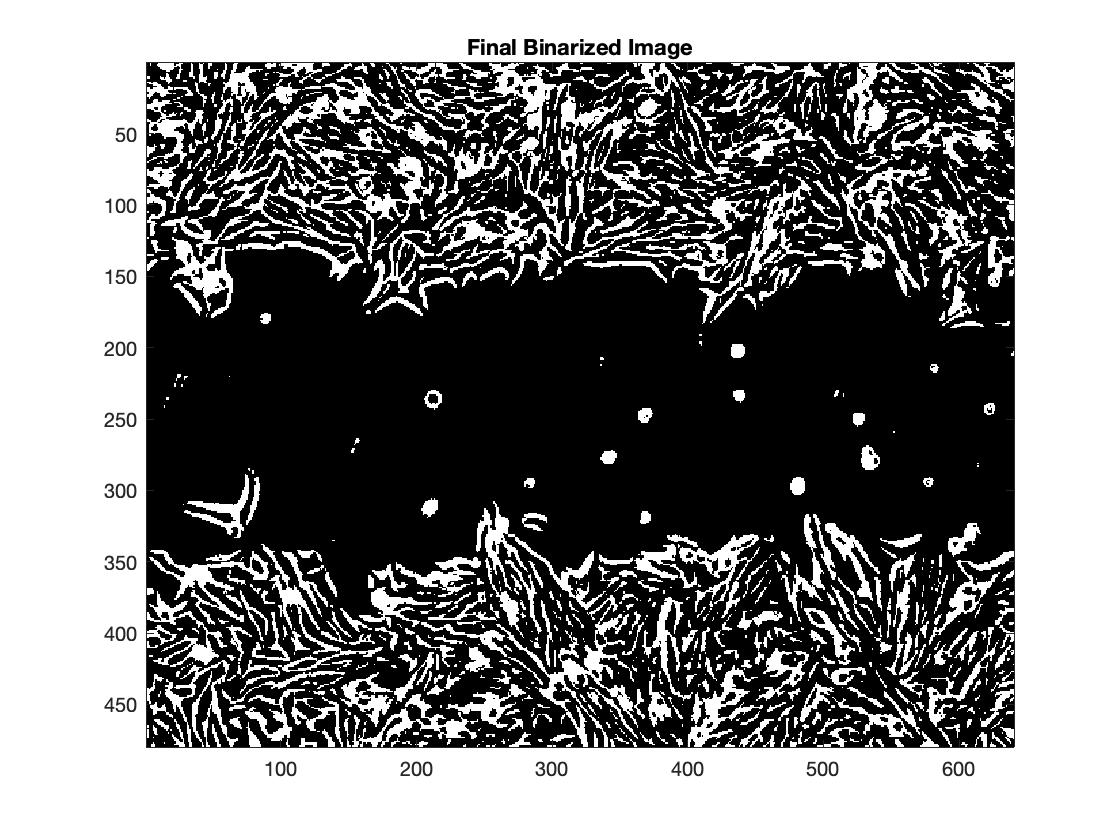

figure, colormap gray
    imagesc(bw), title('Final Binarized Image')  

%divide the image into vertical sections & check average intesnsity
 
% Define the number of sections and their boundaries (you should already have this)
n_sections = 600;
section_boundaries = round(linspace(0, size(img_blurred, 2), n_sections+1)); %(image width is 640 pixels)

% Initialize an array to store the peak values for each section
peak_values = zeros(n_sections, 1);

% Loop over the sections
for i = 1:n_sections
    % Extract the current section from the image
    section = img_blurred(:, section_boundaries(i)+1:min(section_boundaries(i+1), size(img,2)), :);
    
    % Calculate the histogram of the section
    [counts, bins] = imhist(section);
    
    % Find the index of the maximum count value
    [~, max_index] = max(counts);
    
    % Use the corresponding bin value as the peak value
    peak_value = bins(max_index);
    
    % Store the peak value for the current section
    peak_values(i) = peak_value;
%     
%     % Display the current section and its histogram
%     figure;
%     subplot(1,2,1);
%     imshow(section);
%     title(sprintf('Section %d (slice %d-%d)', i, section_boundaries(i)+1, min(section_boundaries(i+1), size(img,2))));
%     subplot(1,2,2);
%     imhist(section);
%     title(sprintf('Histogram of Section %d', i));
end

% Display the peak values
disp(peak_values);

    64
    64
    63
    65
    64
    64
    64
    65
    65
    65
    65
    66
    66
    66
    66
    66
    66
    67
    65
    66
    67
    66
    67
    68
    68
    67
    67
    67
    68
    68
    67
    67
    69
    68
    67
    69
    68
    68
    68
    68
    68
    69
    69
    69
    69
    70
    70
    69
    70
    70
    70
    70
    70
    70
    70
    71
    69
    71
    70
    71
    70
    71
    71
    71
    70
    70
    71
    72
    71
    70
    70
    72
    70
    71
    71
    72
    72
    71
    73
    72
    72
    74
    72
    74
    75
    76
    75
    74
    75
    75
    75
    75
    75
    75
    75
    74
    74
    75
    74
    75
    75
    75
    75
    75
    76
    76
    75
    75
    76
    76
    77
    76
    75
    76
    76
    76
    76
    77
    77
    77
    77
    77
    77
    77
    78
    82
    78
    78
    78
    78
    79
    78
    79
    79
    78
    79
    79
    79
    78
    79
    84
    79
    79


figure
subplot(1,1,1)
hist_image = histogram(peak_values, 10);

% Add labels and title to the plot
xlabel('Peak Values');
ylabel('Frequency');
if otsus_method
    figure_title = "Histogram, otsu's method"
else
    figure_title = "Histogram, adaptive thresholding"
end

figure_title = "Histogram, adaptive thresholding"

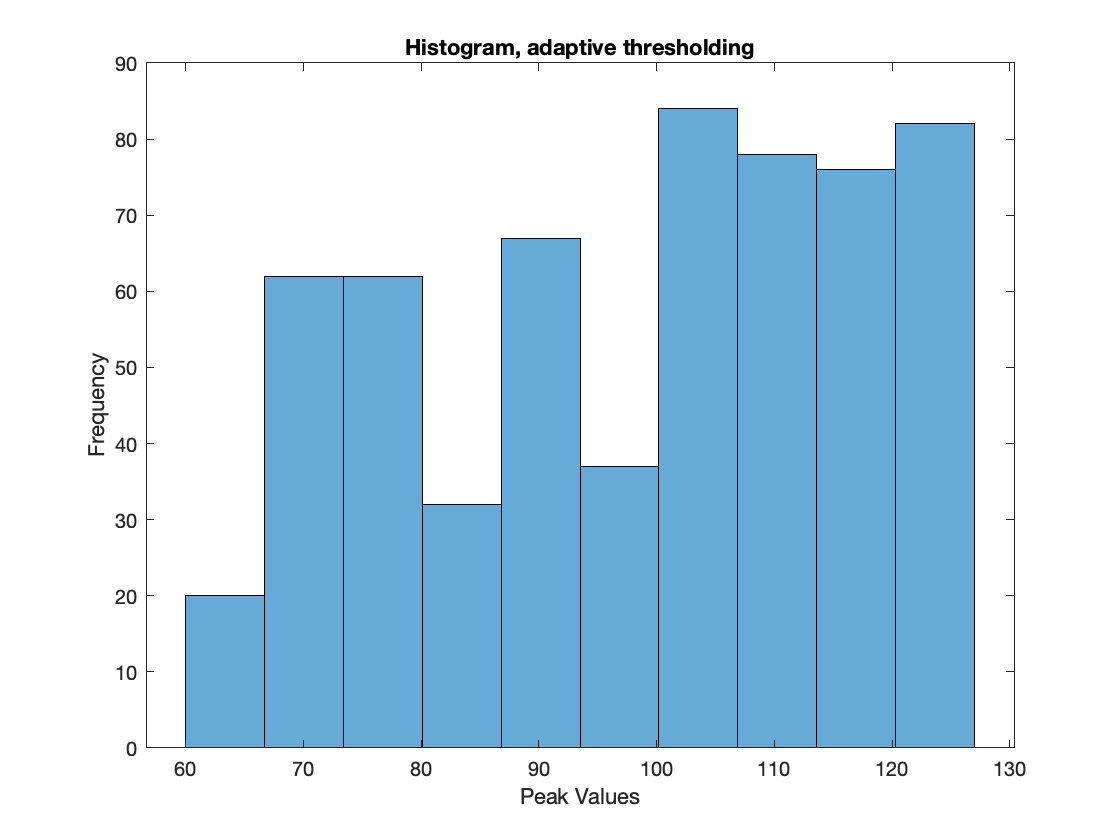


title(figure_title);


std(peak_values);

%get the histogram peak values
freq_threshold = 100;
[counts, bins] = histcounts(peak_values, 20);
bin_indices = find(counts > freq_threshold); %indices of bins with large frequencies
biggest_peaks = bins(bin_indices);
frequencies = counts(bin_indices);
peak_average = 0;
total_freq = 0;
sz = size(bin_indices);

for i = 1:sz(2)
    peak_average = peak_average + biggest_peaks(i)*frequencies(i);
    total_freq = total_freq + frequencies(i);
end
peak_average = peak_average/total_freq

peak_average = NaN


histogram_name = extractBefore(imgTitle, '.tif')+" "+figure_title;

% skip_step = true;  
% 
% if ~skip_step
%     % Label the connected components in the binary image
%     rr = bwlabel(bw);
%     
%     % Extract region properties
%     props = regionprops(rr, 'Area', 'Perimeter', 'BoundingBox');
%     
%     % Calculate roundness for each region
%     roundness = 4 * [props.Area] ./ ([props.Perimeter].^2);
%     
%     roundness_threshold = 0.14; % higher: more strict, lower: less strict (to remove objects)
%     % Remove regions with roundness above a certain threshold
%     
%     size_threshold = 35; % adjust as needed
%     round_objects = roundness > roundness_threshold & [props.Area] > size_threshold;
%     rr(ismember(rr, find(round_objects))) = 0;
%       
%     % Display the resulting binary image
%     fprintf('Round non-cell noise removed')
%     figure 
%     imshow(rr), colormap gray;  
% else
%     rr = bw;
%     fprintf('Step 3 skipped')
%     roundness_threshold = NaN;
%     size_threshold = NaN;
% end

Step 3 skipped

% 
% 


**4. Get rid of small gap noise (simple protocol): **

       
% initial area opening to get rid of small specs in gap


%check off which area opening slider you want to use so that it's easier to precisely
%edit strel size

%small strel option - goes from 0-20 w/ step size 1:
use_little = true;
small_size = 15;

%big strel option - goes from 0-100 w/ step size 5:
use_large = false;
big_size = 50;

if use_large
    initial_area_opening = big_size;
else
    initial_area_opening = small_size;
end

bw2 = bwareaopen(rr,initial_area_opening); 
  
fprintf('Gap Noise Removed:')

Gap Noise Removed:

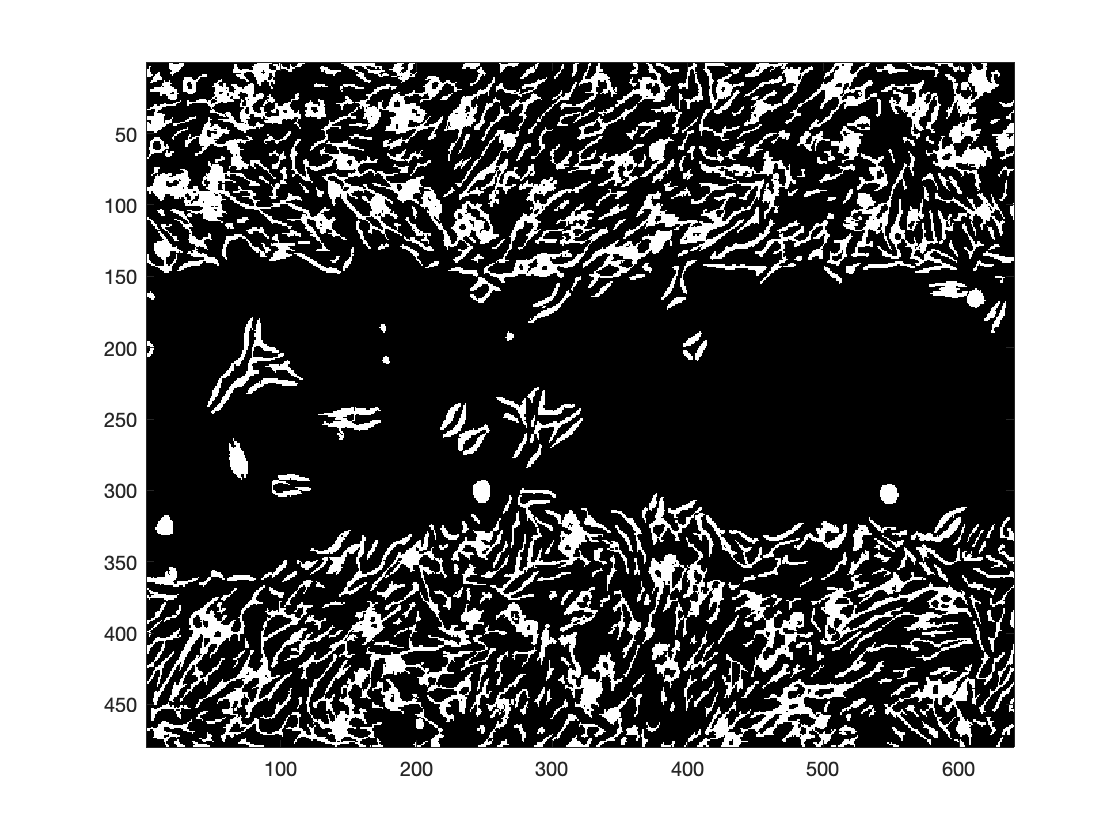


figure
imagesc(bw2), colormap gray

% skip_step = true;   %check this if you want to run this section & skip this extra gap clearing step
% if skip_step
%     strel_size = 0;
% else
%     strel_size =0;
% end
%   
% 
% if strel_size ~= 0
%     fprintf('Initial Dilation for Gap Clearing:')
%     se_a = strel('disk', strel_size);
%     initial_dilation = imdilate(bw2,se_a);
%      
%     imagesc(initial_dilation)
% else
%     fprintf('Step 5a: No further gap clearing necessary.')
% end

Step 5a: No further gap clearing necessary.

%   
% if strel_size ~= 0
%     area_opening_2 = 900;
%     gap_cleared1 = bwareaopen(initial_dilation,area_opening_2);
%   
%     fprintf('Gap Cleared:')
%      
%     imagesc(gap_cleared1)
%     gap_cleared2 = imerode(gap_cleared1,se_a);
% else
%     area_opening_2 = 0;%store gap clearing area opening value as 0 in table
%     fprintf('Step 5b: No further gap clearing necessary.')
%     gap_cleared2 = bw2; % if no additional gap clearing initiated in last section, current image = last version
% end

Step 5b: No further gap clearing necessary.

% 
% 
% % fprintf('previous image to reference for step 7:')
% %  
% % imagesc(gap_cleared2)



**6a) segment automatically with dilation & erosion:**

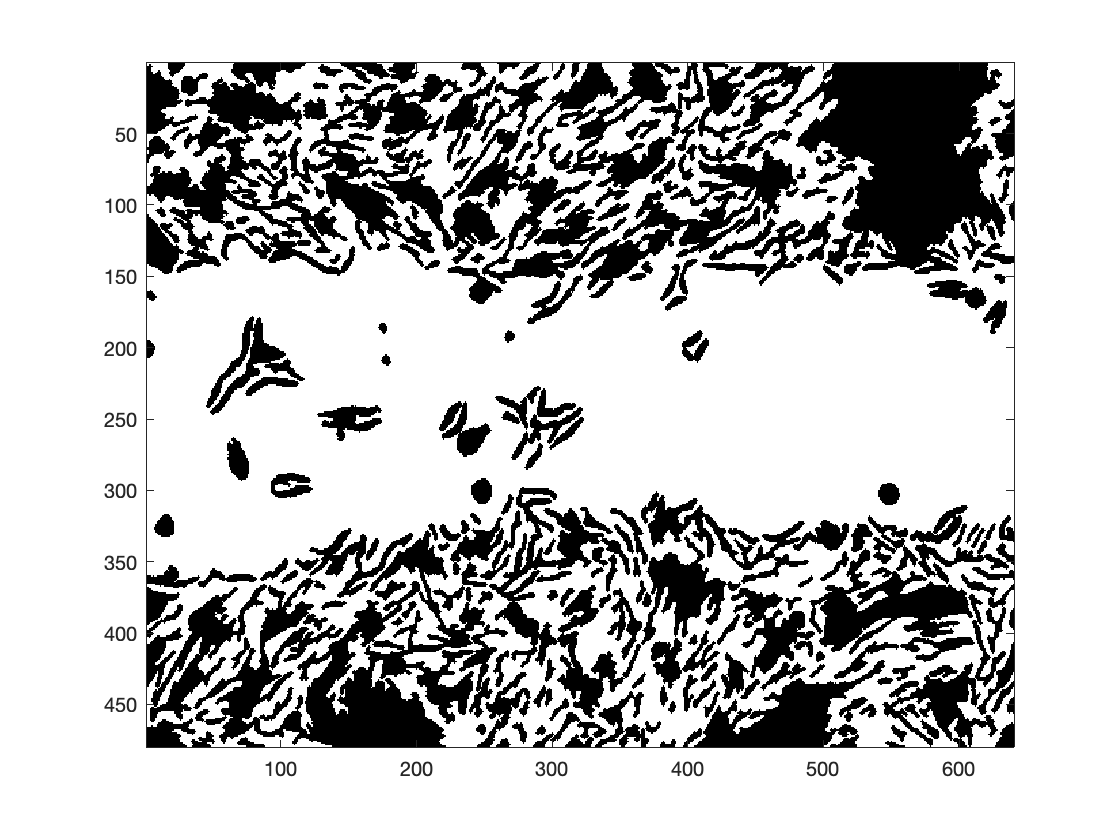

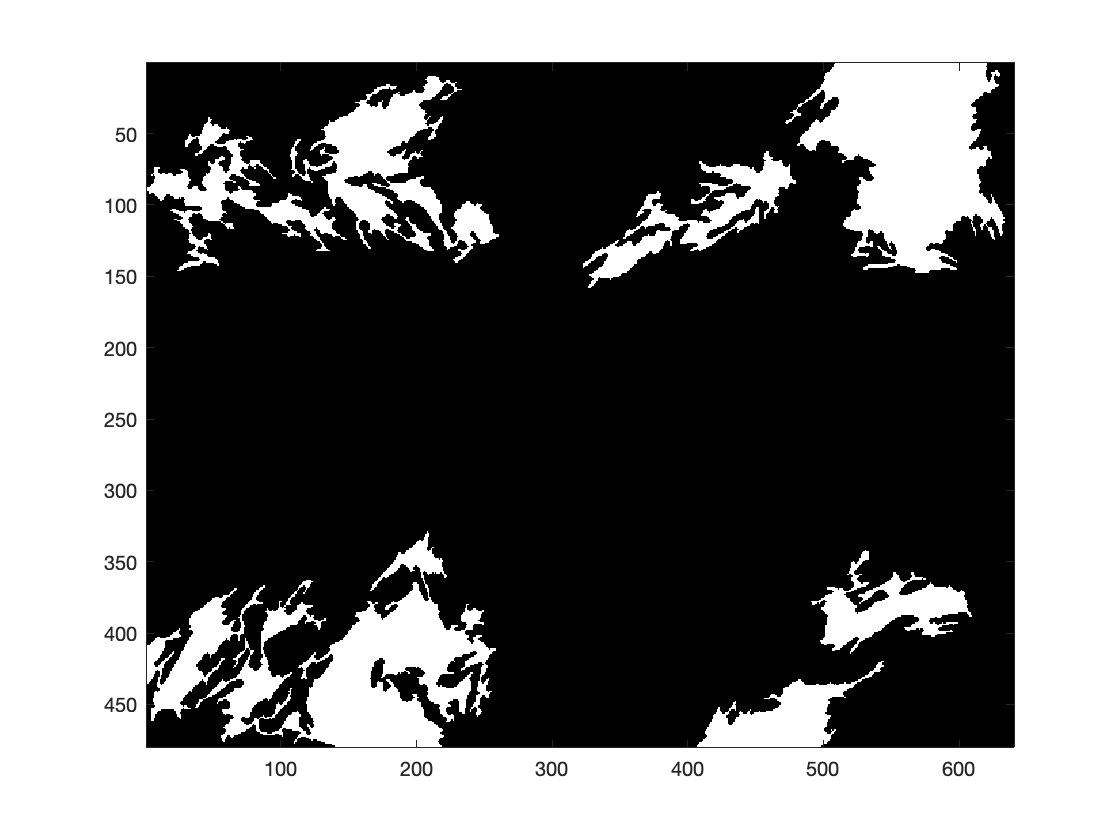

Strel size = 1

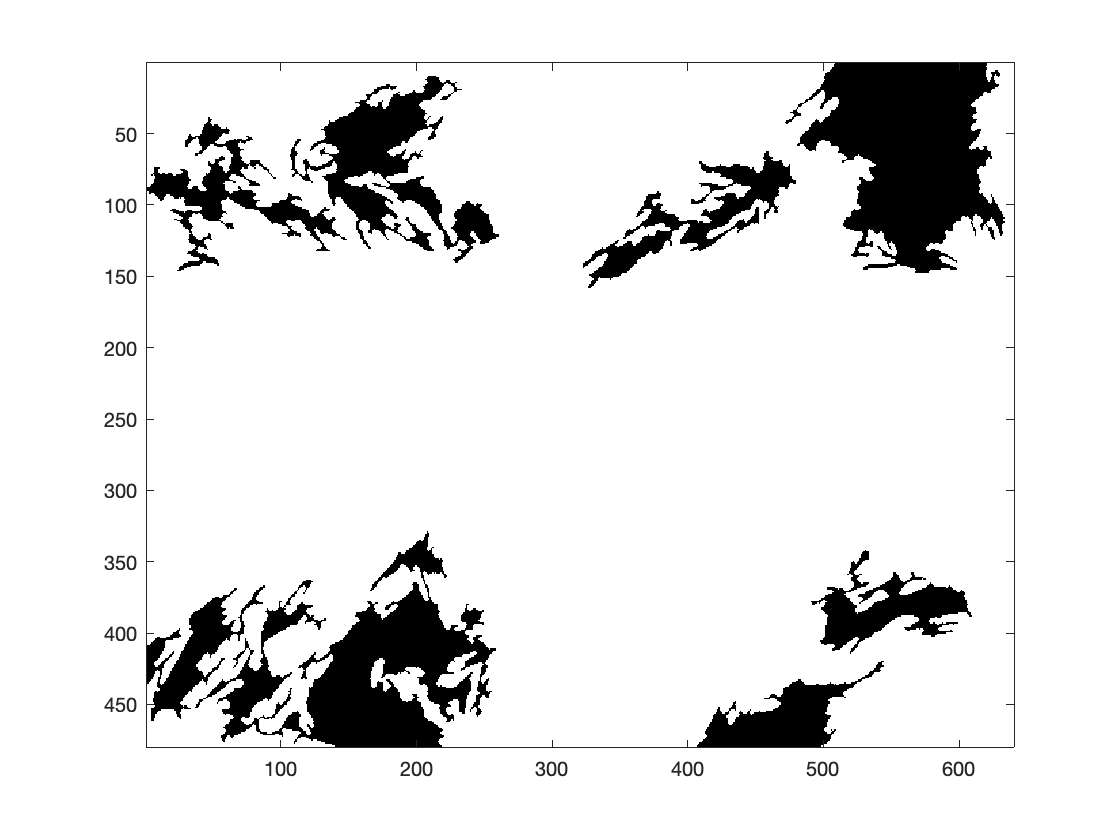

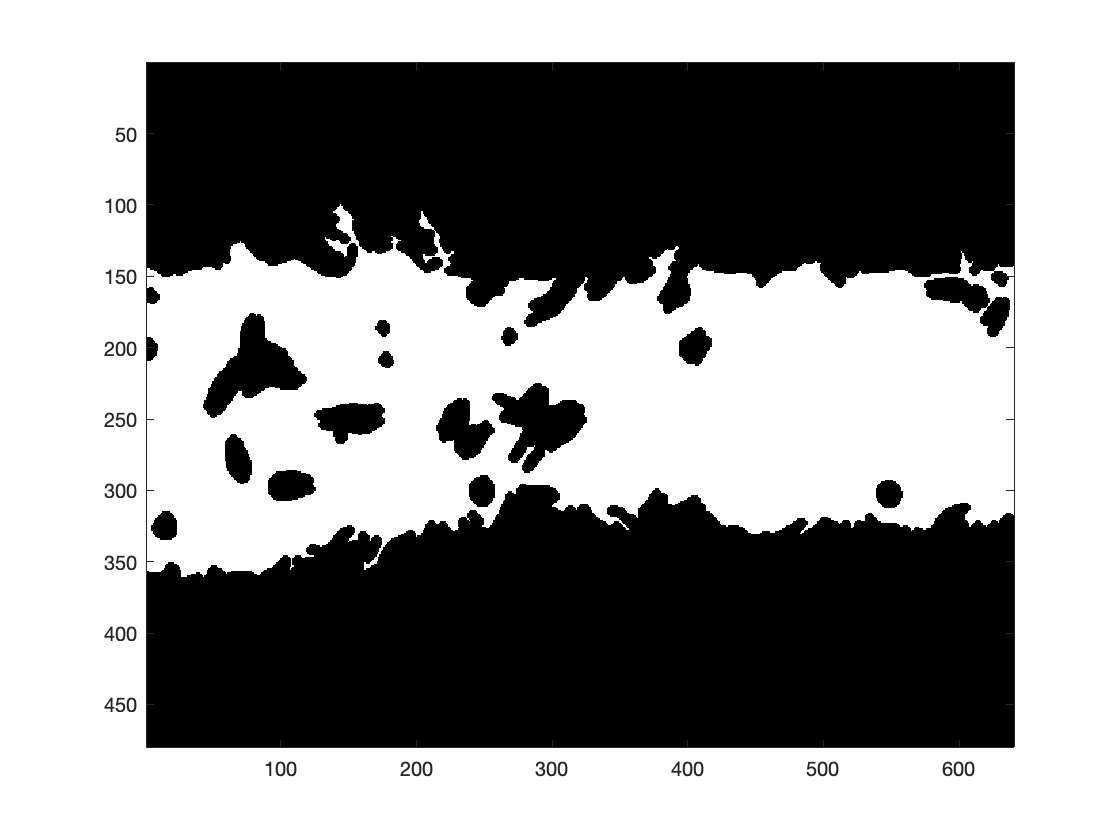

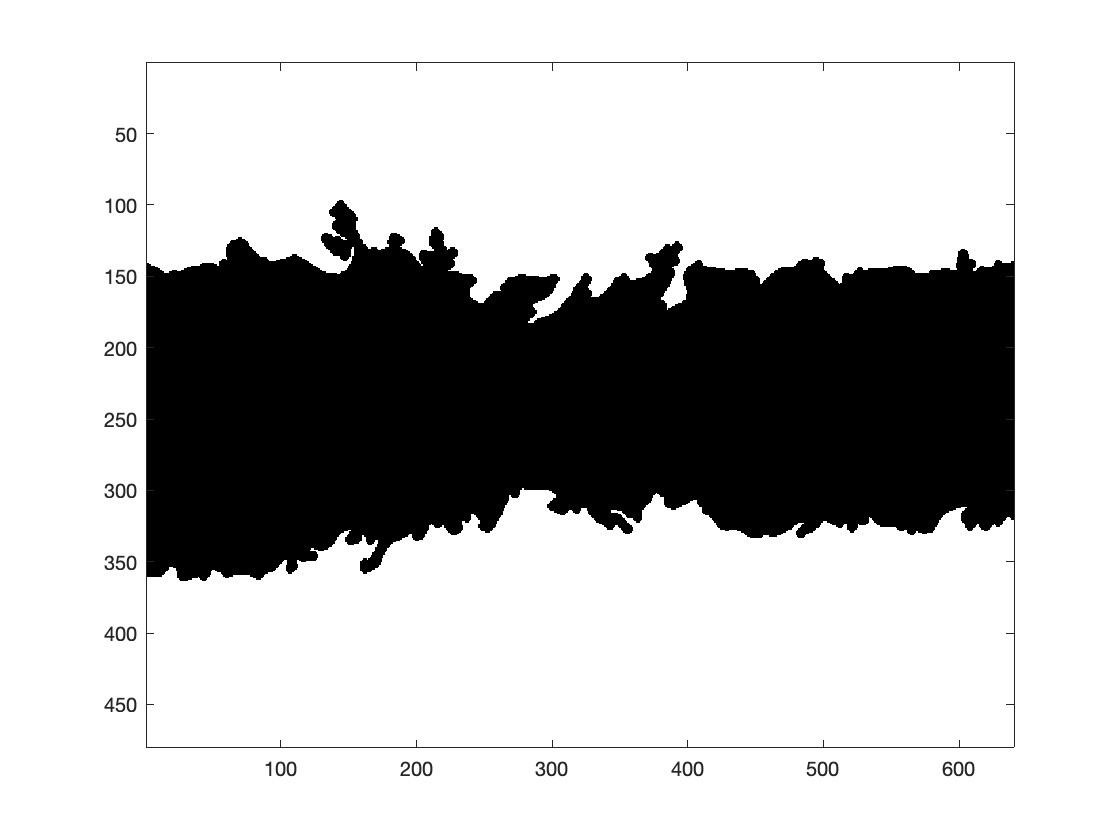

Strel size = 4

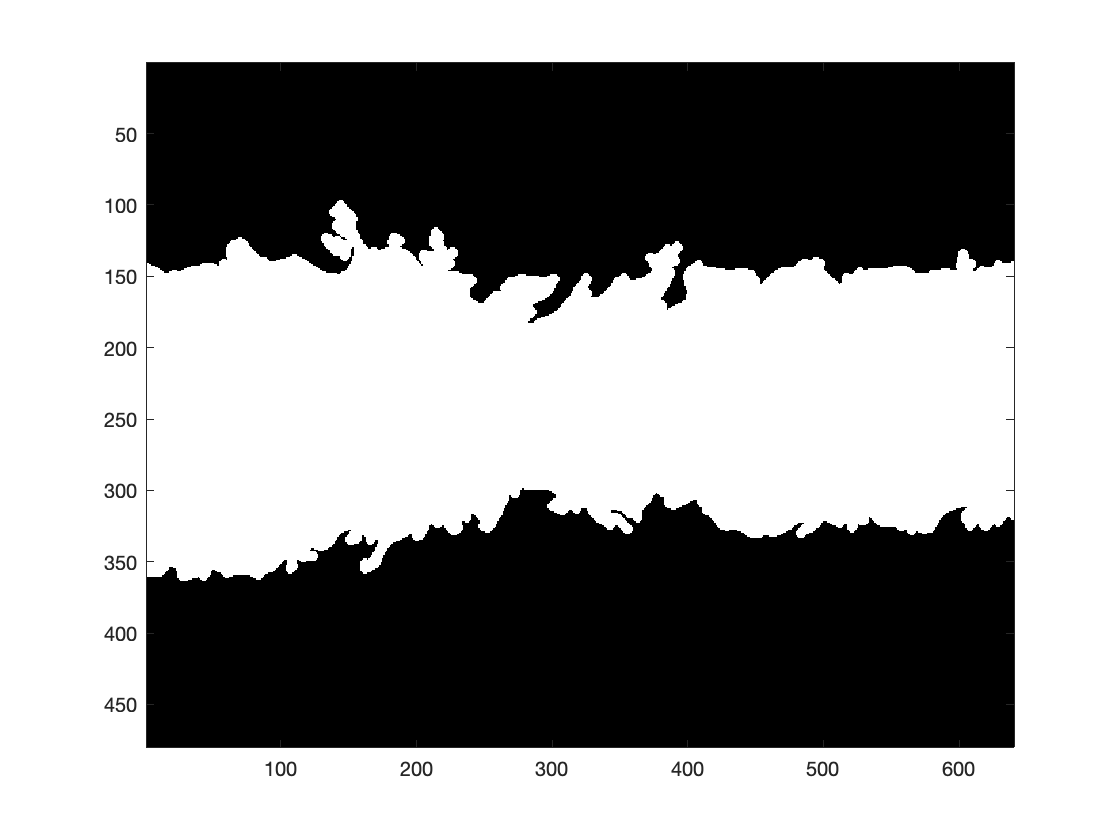

 

strel_range = 1:3:60;
complement = gapSegmentation(gap_cleared2, strel_range); % assign the final image to the var complement


%show the final image & display its strel size used 
global final_strel
main_strel = final_strel; % for stats table
fprintf('[Strel size = %d] compared to original:', final_strel); % label the comparison here so that we have the right value of i (inside a for loop)

[Strel size = 4] compared to original:

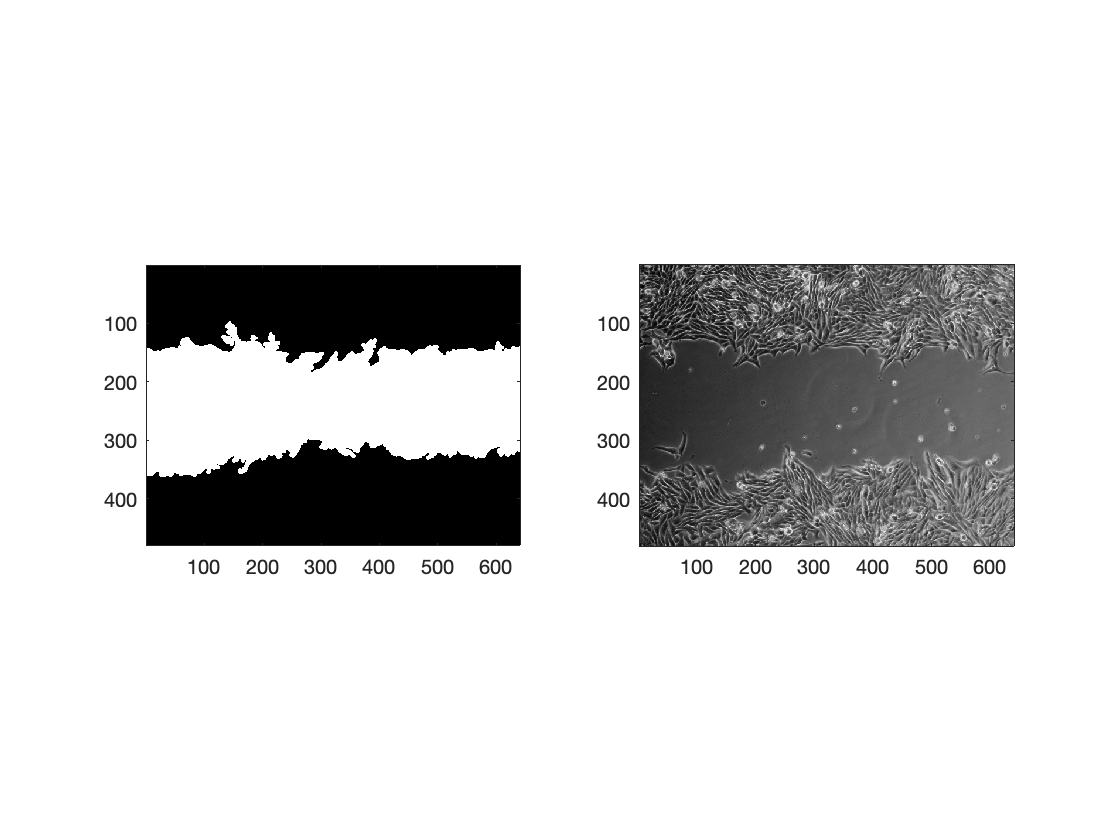

figure, colormap gray
subplot(1,2,1);
imagesc(complement), axis image, colormap gray;
subplot(1,2,2);
imagesc(img), axis image, colormap gray;

final_image = complement;

%  
% further_dilation = false; 
% if further_dilation
%     strel_size_2 = final_strel+2;
%     main_strel = strel_size_2; %for stats table
%     further_dilation_ = dilateErode(gap_cleared2, strel_size_2);
%      
%     fprintf('[Strel size = %d] compared to original:', main_strel); %label the comparison
%     figure
%     subplot(1,2,1);
%     imagesc(further_dilation_), axis image, colormap gray;
%     subplot(1,2,2);
%     imagesc(img), axis image, colormap gray;
%     final_image2 = further_dilation_;
% else
%     fprintf('6b: No further dilation performed.')
%     final_image2 = final_image;
% end

6b: No further dilation performed.

**7. Create/Download Montage & Analysis Stats: **Once you've ensured the analysis is correct in step 8, create & download a montage of the original vs final image to your current folder.  Insert table name where you want to store data & the file path/folder where you want it to be located. (If a file with that name & location does not already exist, it will be created).

%where store data from image analysis (table & montage)
tableName = "KaileyMigrationData"+'.xls'; %excel file where you want to store analysis stats
filePath = "/Users/elizabeth 1/Desktop/Wu Lab/Kaileys Images/9a_Migration Analysis";  %directory in which to create/look for table & to store images
cd(filePath)


 
%produce montage

C = imfuse(final_image2,img,'montage');

S = extractBefore(imgTitle, '.tif');
fileName = "MONTAGE " + S + '.jpg';
imwrite(C,fileName)



fprintf('Image Montage (Downloaded): [%s]', fileName)

Image Montage (Downloaded): [MONTAGE E2 24h.jpg]

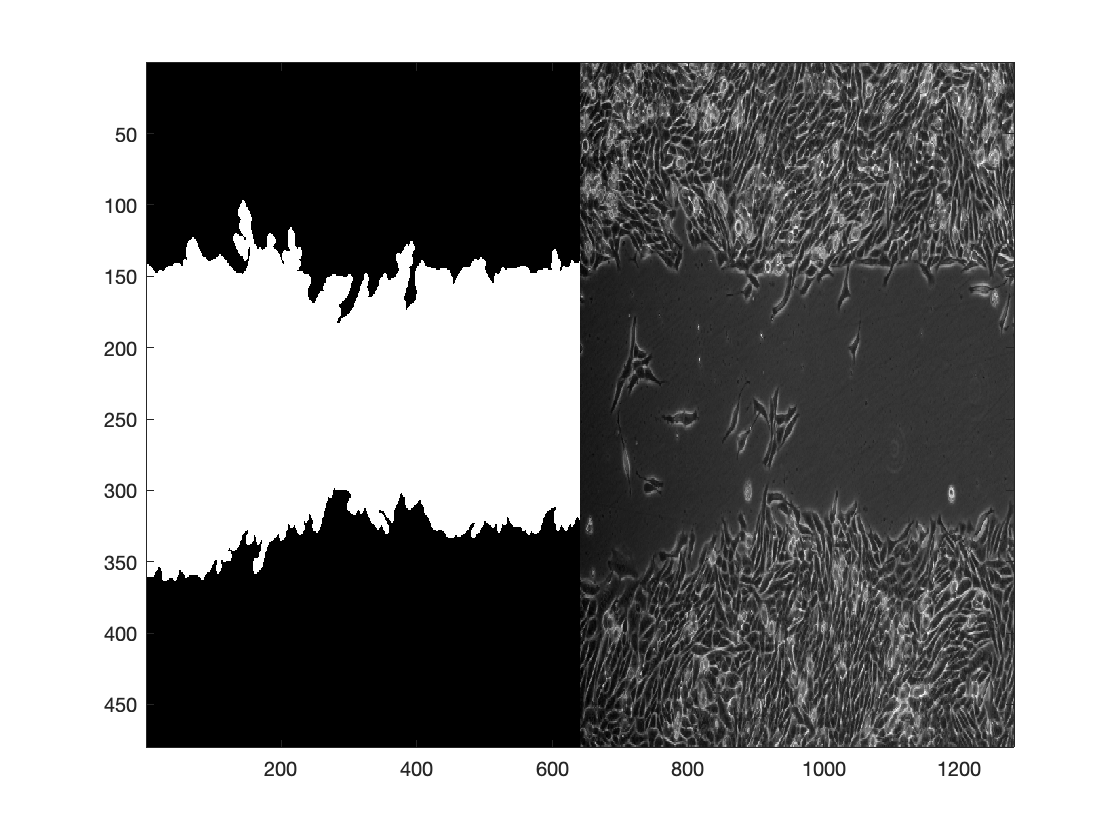

subplot(1,1,1);
imagesc(C), colormap gray


%calculate gap area
stats = regionprops(final_image2, 'Area');
    allAreas = [stats.Area];
    gapArea = max(allAreas);  
clipboard('copy',gapArea)  
fprintf('Final Gap Area = %d\n', gapArea)

Final Gap Area = 120480



figure
subplot(1,1,1)
hist_image = histogram(peak_values, 10);

% Add labels and title to the plot
xlabel('Peak Values');
ylabel('Frequency');
if otsus_method
    figure_title = "Histogram, otsu's method"
else
    figure_title = "Histogram, adaptive thresholding"
end

figure_title = "Histogram, adaptive thresholding"

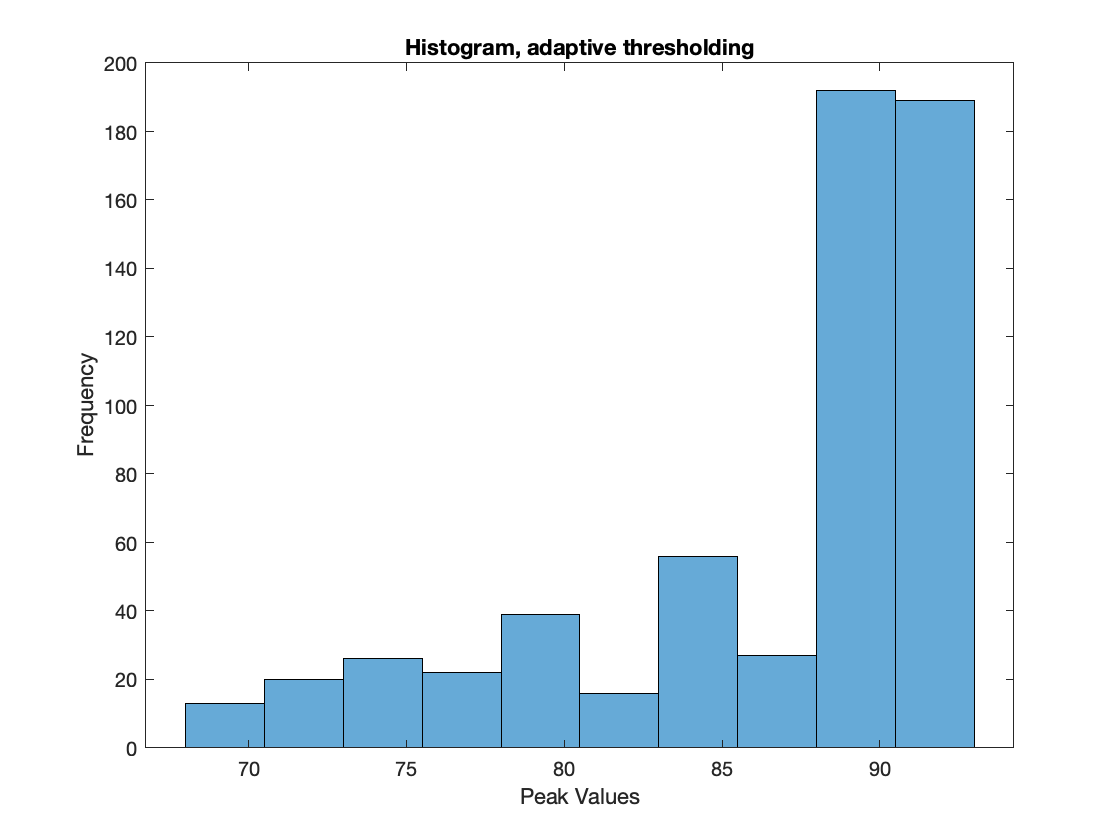


title(figure_title);
saveas(gcf, histogram_name)


%create an excel file with tableName if such a file does not already exist;
if ~isfile(tableName) %if the table does not already exist
    colNames = {'Photo Name', 'gap area (pixels)', 'threshold', 'roundness threshold','size threshold','open size', 'gap clear strel', 'gap clear open size', 'main strel'};
    data = cell(1,9); % create a cell array with one row and the same number of columns as colNames
    table = [cell2table(colNames, 'VariableNames', colNames); cell2table(data, 'VariableNames', colNames)]
    writetable(table, tableName);
    existingTable = readtable(tableName);
    existingTable(1,:) = []; %remove duplicate column names row
else
    existingTable = readtable(tableName); %no need to remove duplicate col name row in this case
end

if manual_thresholding
    x = manual_threshold;
    threshold = [num2str(x) ' (manual)'];
elseif adaptive_thresholding
    x = adaptive_sensitivity;
    threshold = [num2str(x) ' (adaptive)'];
elseif otsus_method
    x = threshold_otsu;
    threshold = [num2str(x) ' (Otsu)']
elseif dark_adaptive
    threshold = 'dark adaptive';
end


fprintf('This table is stored as %s in %s:', tableName, filePath)

This table is stored as KaileyMigrationData.xls in /Users/elizabeth 1/Desktop/Wu Lab/Kaileys Images/9a_Migration Analysis:


newRow = {imgTitle, gapArea, threshold, roundness_threshold, size_threshold, initial_area_opening, strel_size, area_opening_2, main_strel}; 

data = [existingTable;newRow]; %add data from analysis
%T = unique(data,'rows', 'stable'); %make sure there are no duplicate lines
% Find the unique values in PhotoName column
[~, ia, ~] = unique(flipud(data.PhotoName),'rows', 'stable');
ia = size(data,1) - ia + 1;% Select only the rows that contain unique values. If you ran code for
% the same image >1 time, the program will save the most recent version of
analysisStats = flipud(data(ia, :))

analysisStats = 31×9 table
         PhotoName          gapArea_pixels_         threshold         roundnessThreshold    sizeThreshold    openSize    gapClearStrel    gapClearOpenSize    mainStrel
    ____________________    _______________    ___________________    __________________    _____________    ________    _____________    ________________    _________

    "C1 0h.tif"               1.4112e+05       {'0.5 (adaptive)' }            NaN                NaN             5             0                   0             10    
    "C2 0h.tif"               1.4112e+05       {'0.43 (manual)'  }            NaN                NaN            20             0                   0              


writetable(analysisStats, tableName, 'WriteMode', 'overwrite'); %add data to table